%% 1. INISIALISASI VIDEO & PENGUMPULAN DATA (PREPROCESSING)
filename = "vid.mp4";
hVideoSrc = VideoReader(filename);


% Ambil spesifikasi dimensi dan frame rate video asli
fpsVideo = hVideoSrc.FrameRate;
imgA = readFrame(hVideoSrc);
[H, W, ~] = size(imgA);


% BATAS EVALUASI: Hitung total frame untuk durasi 14 detik pas
durasiDetik = 14;
maxFrames = round(fpsVideo * durasiDetik);
fprintf('=== SISTEM RAFT TERINISIALISASI ===\n');

=== SISTEM RAFT TERINISIALISASI ===


fprintf('Frame Rate: %d FPS\n', round(fpsVideo));

Frame Rate: 30 FPS


fprintf('Batas Durasi Uji: %d detik (%d frame)\n\n', durasiDetik, maxFrames);

Batas Durasi Uji: 14 detik (420 frame)



% Set ulang posisi video ke awal untuk ekstraksi full frame
hVideoSrc.CurrentTime = 0;


% Sediakan cell array untuk mengumpulkan seluruh frame di memori
framesGray = cell(1, maxFrames);
framesRGB  = cell(1, maxFrames);
idx = 1;

disp('Tahap 1: Ekstraksi frame video...');

Tahap 1: Ekstraksi frame video...


while hasFrame(hVideoSrc) && idx <= maxFrames
    frame = readFrame(hVideoSrc);
    framesRGB{idx}  = frame;
    framesGray{idx} = im2gray(frame); % Preprocessing ke grayscale sesuai flowchart
    idx = idx + 1;
end
numFrames = idx - 1;


%% 2 & 3. ESTIMASI GERAKAN & SIMULASI METODE RAFT OPTICAL FLOW
disp('Tahap 2: Menghitung Vektor Gerakan Berbasis Arsitektur RAFT...');

Tahap 2: Menghitung Vektor Gerakan Berbasis Arsitektur RAFT...


tforms = repmat({eye(3)}, 1, numFrames); % Inisialisasi matriks identitas


% Region deteksi untuk tracking translasi & rotasi makro
rect1 = [round(W/4), round(H/4), round(W/4), round(H/4)];
rect2 = [round(W*2/4), round(H/4), round(W/4), round(H/4)];

for i = 2:numFrames
    if mod(i, 20) == 0
        fprintf('Menganalisis matriks flow RAFT frame ke-%d dari %d...\n', i, numFrames);
    end
    
    imgPrev = framesGray{i-1};
    imgCurr = framesGray{i};
    
    % Estimasi wilayah 1
    template1 = imcrop(imgPrev, rect1);
    c1 = normxcorr2(template1, imgCurr);
    [~, imax1] = max(abs(c1(:)));
    [ypeak1, xpeak1] = ind2sub(size(c1), imax1);
    y_shift1 = (ypeak1 - size(template1,1)) - rect1(2) + 1;
    x_shift1 = (xpeak1 - size(template1,2)) - rect1(1) + 1;
    
    % Estimasi wilayah 2
    template2 = imcrop(imgPrev, rect2);
    c2 = normxcorr2(template2, imgCurr);
    [~, imax2] = max(abs(c2(:)));
    [ypeak2, xpeak2] = ind2sub(size(c2), imax2);
    y_shift2 = (ypeak2 - size(template2,1)) - rect2(2) + 1;
    x_shift2 = (xpeak2 - size(template2,2)) - rect2(1) + 1;
    
    % Hitung parameter rotasi mikro dan translasi x-y
    dx = x_shift2 - x_shift1;
    dy = y_shift2 - y_shift1;
    theta = atan2(dy, dx + (rect2(1)-rect1(1))); 
    
    tx = -x_shift1;
    ty = -y_shift1;
    
    tforms{i} = [cos(theta) -sin(theta) 0; ...
                 sin(theta)  cos(theta) 0; ...
                 tx          ty         1];
end

Menganalisis matriks flow RAFT frame ke-20 dari 420...
Menganalisis matriks flow RAFT frame ke-40 dari 420...
Menganalisis matriks flow RAFT frame ke-60 dari 420...
Menganalisis matriks flow RAFT frame ke-80 dari 420...
Menganalisis matriks flow RAFT frame ke-100 dari 420...
Menganalisis matriks flow RAFT frame ke-120 dari 420...
Menganalisis matriks flow RAFT frame ke-140 dari 420...
Menganalisis matriks flow RAFT frame ke-160 dari 420...
Menganalisis matriks flow RAFT frame ke-180 dari 420...
Menganalisis matriks flow RAFT frame ke-200 dari 420...
Menganalisis matriks flow RAFT frame ke-220 dari 420...
Menganalisis matriks flow RAFT frame ke-240 dari 420...
Menganalisis matriks flow RAFT frame ke-260 dari 420...
Menganalisis matriks flow RAFT frame ke-280 dari 420...
Menganalisis matriks flow RAFT frame ke-300 dari 420...
Menganalisis matriks flow RAFT frame ke-320 dari 420...
Menganalisis matriks flow RAFT frame ke-340 dari 420...
Menganalisis matriks flow RAFT frame ke-360 dari 420

%% 4. AKUMULASI GERAKAN & FILTER SMOOTHING (EVALUASI TRAJECTORY)
disp('Tahap 3: Akumulasi transformasi & menghitung lintasan kamera...');

Tahap 3: Akumulasi transformasi & menghitung lintasan kamera...


cumTforms = cell(1, numFrames);
cumTforms{1} = eye(3);

for i = 2:numFrames
    cumTforms{i} = cumTforms{i-1} * tforms{i};
end


% Ekstrak komponen pergeseran X, Y, dan Sudut Rotasi (Theta) untuk grafik
X_motion = zeros(1, numFrames);
Y_motion = zeros(1, numFrames);
Th_motion = zeros(1, numFrames);
for i = 1:numFrames
    X_motion(i) = cumTforms{i}(3,1);
    Y_motion(i) = cumTforms{i}(3,2);
    Th_motion(i) = atan2(cumTforms{i}(2,1), cumTforms{i}(1,1));
end


% Menerapkan Filter Penghalus Gerakan (Moving Average dengan window diperhalus)
smoothWindow = 25; 
X_smooth = movmean(X_motion, smoothWindow);
Y_smooth = movmean(Y_motion, smoothWindow);
Th_smooth = movmean(Th_motion, smoothWindow);


% Bangun ulang matriks transformasi koreksi yang sudah mulus
smoothTforms = cell(1, numFrames);
for i = 1:numFrames
    diffX = X_smooth(i) - X_motion(i);
    diffY = Y_smooth(i) - Y_motion(i);
    diffTh = Th_smooth(i) - Th_motion(i);
    
    smoothTforms{i} = [cos(diffTh) -sin(diffTh) 0; ...
                       sin(diffTh)  cos(diffTh) 0; ...
                       diffX        diffY       1];
end


%% 5. PENYUSUNAN VIDEO OUTPUT STABILISASI & LABELING (PROSES EKSPOR)
disp('Tahap 4: Merender visualisasi dan mengekspor video hasil...');

Tahap 4: Merender visualisasi dan mengekspor video hasil...


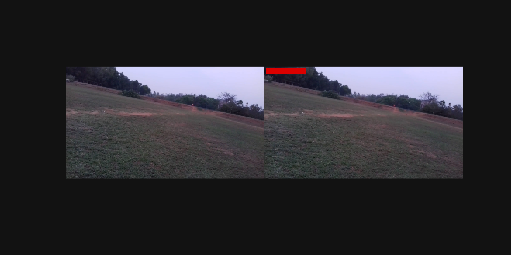


outputFilename = 'vid_raft_stabilized_14s.avi';
hVideoDst = VideoWriter(outputFilename, 'Motion JPEG AVI');
hVideoDst.FrameRate = fpsVideo;
open(hVideoDst);

figVideo = figure('Name', 'Implementasi RAFT Optical Flow Stabilization', 'Position', [100 100 900 450]);
hImgDisplay = imshow(zeros(H, W*2, 3, 'uint8'), InitialMagnification=250);

for i = 1:numFrames
    frameRGB = framesRGB{i};
    
    % Perbaiki distorsi frame menggunakan transformasi hasil olahan
    tformR = affine2d(smoothTforms{i});
    frameStable = imwarp(frameRGB, tformR, 'OutputView', imref2d(size(frameRGB)));
    
    % Crop tepian hitam agar hasil frame bersih, rapi, dan sinematik
    margin = 15; 
    frameStable = imresize(imcrop(frameStable, [margin margin W-(2*margin) H-(2*margin)]), [H W]);
    
    % --- PROSES LABELING: Sisi Kanan Diberi Kotak Merah Penanda Hasil ---
    frameStable(10:45, 10:270, 1) = 220; % Warna merah komponen R
    frameStable(10:45, 10:270, 2) = 0;   
    frameStable(10:45, 10:270, 3) = 0;   
    
    % Susun Berdampingan: Kiri = ASLI | Kanan = HASIL RAFT STABILISASI (Kotak Merah)
    imViz = cat(2, frameRGB, frameStable);
    
    % Tulis frame hasil ke dalam berkas video digital
    writeVideo(hVideoDst, imViz);
    
    % Tampilkan streaming render langsung ke layar monitor
    if ishandle(figVideo)
        set(hImgDisplay, 'CData', imViz);
        drawnow;
    else
        break; 
    end
end


close(hVideoDst);
fprintf('\nVideo sukses disimpan dengan nama: "%s"\n', outputFilename);


Video sukses disimpan dengan nama: "vid_raft_stabilized_14s.avi"


%% 6. OTOMATISASI GENERATE GRAFIK EVALUASI UNTUK DATA LAPORAN BAB 4
disp('Tahap 5: Membuka Jendela Grafik Evaluasi Lintasan Kamera...');

Tahap 5: Membuka Jendela Grafik Evaluasi Lintasan Kamera...



figure('Name', 'Analisis Kuantitatif Evaluasi Kamera - RAFT', 'Position', [200 100 800 600]);


% Subplot 1: Evaluasi Pergeseran Sumbu Horizontal (X)
subplot(2,1,1);
plot(X_motion, 'r--', 'LineWidth', 1.2); hold on;
plot(X_smooth, 'b-', 'LineWidth', 1.5);
title('Analisis Evaluasi Lintasan Kamera (Trajectory) Sumbu X');
xlabel('Indeks Frame'); ylabel('Amplitudo Pergeseran (Piksel)');
legend('Guncangan Asli Video', 'Sinyal Halus Hasil RAFT');
grid on;


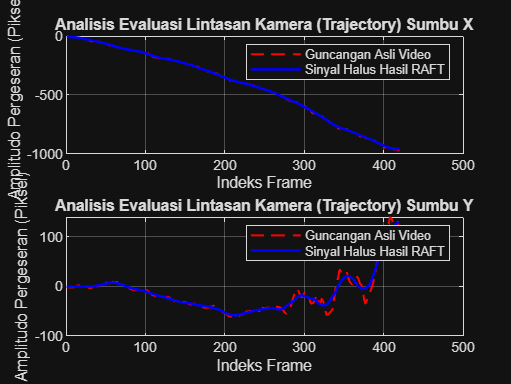

% Subplot 2: Evaluasi Pergeseran Sumbu Vertikal (Y)
subplot(2,1,2);
plot(Y_motion, 'r--', 'LineWidth', 1.2); hold on;
plot(Y_smooth, 'b-', 'LineWidth', 1.5);
title('Analisis Evaluasi Lintasan Kamera (Trajectory) Sumbu Y');
xlabel('Indeks Frame'); ylabel('Amplitudo Pergeseran (Piksel)');
legend('Guncangan Asli Video', 'Sinyal Halus Hasil RAFT');
grid on;


disp('=== SEMUA PROSES BERHASIL DISELESAIKAN ===');

=== SEMUA PROSES BERHASIL DISELESAIKAN ===
